# Analysis of Covid-19 WHO data

## Setup the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 9);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["date", "day", "month", "year", "cases", "deaths", "location", "geo_id", "population"];
opts.VariableTypes = ["datetime", "double", "double", "double", "double", "double", "categorical", "categorical", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["location", "geo_id"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "date", "InputFormat", "dd/MM/yyyy");

% Import the data

Source [https://www.ecdc.europa.eu/sites/default/files/documents/COVID-19-geographic-disbtribution-worldwide.csv](https://www.ecdc.europa.eu/sites/default/files/documents/COVID-19-geographic-disbtribution-worldwide.csv)

url = 'https://www.ecdc.europa.eu/sites/default/files/documents/COVID-19-geographic-disbtribution-worldwide.csv';
% TODO: work out how to download this
filename = 'COVID-19-geographic-disbtribution-worldwide.csv';
tbl = readtable(filename, opts);
% Sample 10 rows for preview
tbl( floor(rand(10,1)*height(tbl)), : )

ans = 10×9 table
       date       day    month    year    cases    deaths            location            geo_id    population
    __________    ___    _____    ____    _____    ______    ________________________    ______    __________
    25/02/2020    25       2      2020       1       0       Singapore                     SG      5.6387e+06
    01/03/2020     1       3      2020       9       0       Norway                        NO      5.3143e+06
    25/02/2020    25       2      2020       0       0       Finland                       FI      5.5181e+06
    27/01/2020    27       1      2020       1       0       United_Arab_Emirates          AE       9.631e+06
    29/02/2020   

## Clear temporary variables

clear opts

## Group by country 

[G,ID] = findgroups( tbl.location);
by_country = table;
by_country.name = ID;

### Calculate total cases & deaths

for n = 1:numel(ID)
    ix = find(G == n);
    tbl{ix,'total_deaths'}  = cumsum( tbl{ix,'deaths'}, 'reverse' );
    tbl{ix,'total_cases'}   = cumsum( tbl{ix,'cases'}, 'reverse' );
end
by_country.total_deaths = splitapply( @max, tbl.total_deaths, G );
by_country.total_cases = splitapply( @max, tbl.total_cases, G );

### Find date of 10th death

by_country.date_deaths_10 = splitapply( @(t,dt) findExeedanceDate(t,dt,10), tbl.date, tbl.total_deaths , G );

### Plot each country from date of 10th death

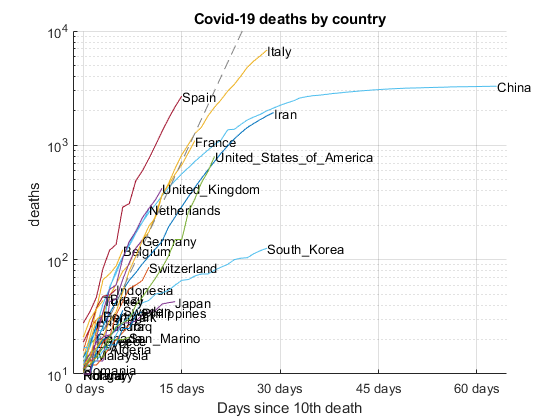

% Setup figure & axis
fig = figure; ax = axes;
ax.NextPlot = 'add';
ax.YScale ='log';
for id = ID'
    % Get single country summary
    country = by_country(by_country.name == id,:);
    
    % Index relevant data from main table
    ix = tbl.location == id & tbl.date >= country.date_deaths_10; 
    
    % Skip country if no relevant rows
    if ~any(ix); continue; end 
    
    % Calculate relative dates
    dt = tbl.date(ix) - country.date_deaths_10;
    
    % Plot rate of deaths
    y = tbl.total_deaths(ix);
    semilogy(dt, y)
    text(dt(1),y(1),strrep(char(id),'_','\_'))
end

% Get time base
X = ax.XTick;

% Format chart
d = duration(X,'Format','d');
ax.XTickLabel = char(d);
xlabel('Days since 10th death')
ylabel( 'deaths ')
title('Covid-19 deaths by country' )
grid on
ax.YLimMode = 'manual';
ax.XLimMode = 'manual';

% Apply 33% growth line
Y = 10*(1.33).^days(X);
semilogy(X, Y,'--','Color',[128 128 128] / 255)

function dt = findExeedanceDate( dates, value, threshold )
[dates,ix] = sort(dates,'ascend');
value = value(ix);

ix = value >= threshold;
if any(ix)
    dt = dates( find(ix,1) );
else
    dt = NaT;
end
end